    % load the audio
    audio = '/Users/myonyinyimin/Documents/MATLAB/Lab-1/Audio/en.wav';
    [audio_data,fs]=audioread(audio);
    
    % To Display sampling rate
    disp(['Sampling Rate:', num2str(fs), 'Hz']);

Sampling Rate:44100Hz


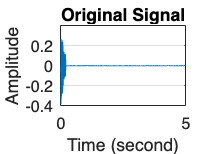

    
    % Play the audio to check it is correctly loaded or not
    sound(audio_data, fs);
    
    % Plotting the audio signal using time vector
    time_vector = (0:length(audio_data)-1) / fs;
    figure;
    plot(time_vector,audio_data);
    title('Original Signal');
    xlabel('Time (second)');
    ylabel('Amplitude');
    grid on;

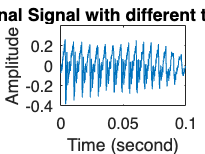

    
    % Zoom in the plot
    plot(time_vector, audio_data);
    title('Original Signal with different time frame');
    xlabel('Time (second)');
    ylabel('Amplitude');
    xlim([0, 0.1]); 

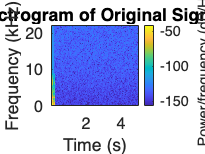


    % Spectrogram plot
    figure;
    spectrogram(audio_data, 256, [], [], fs, 'yaxis');
    title('Spectrogram of Original Signal');

    
    % Find Standard Deviation
    min_value = min(audio_data);
    max_value = max(audio_data);
    disp(['Min value: ', num2str(min_value)]);

Min value: -0.38361


    disp(['Max value: ', num2str(max_value)]);

Max value: 0.26486


    disp(['Standard deviation: ', num2str(std(audio_data))]);

Standard deviation: 0.019185


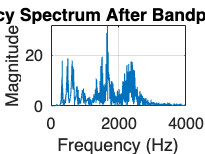

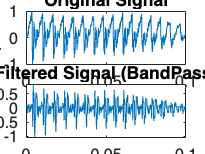

    
    % Normalization
     min_value = min(audio_data);
     max_value = max(audio_data);
     normalized_data = 2 * (audio_data - min_value) / (max_value - min_value) - 1;
    
    % Call function for cutoff Frequency
    [lower_cutoff, upper_cutoff] = findCutoffFrequency(normalized_data, fs);
    [filter_signal, magnitude_axis, frequency_axis] = AudioCleaning(normalized_data,fs,lower_cutoff, upper_cutoff);

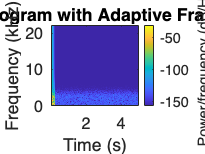

    
    sound(filter_signal, fs);
    
    %Framing
    [frame_size, frame_overlap] = Framing(filter_signal,magnitude_axis,fs);
    frames = Framing_function(filter_signal,frame_size,frame_overlap);
        
    window = hamming(frame_size);
    figure;
    spectrogram(filter_signal,window,frame_overlap,[],fs,'yaxis');
    title('Spectrogram with Adaptive Framing');

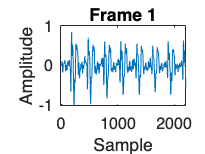

    
    % Plot one frame to verify
    frame_index = 1;
    figure;
    plot(frames(frame_index, :));
    title(['Frame ', num2str(frame_index)]);
    xlabel('Sample');
    ylabel('Amplitude');

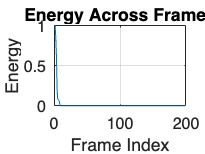

    
    % Energy Calculation
    energy = Energy_Calcu_Function(frames);

    disp(energy);

    1.0000    0.8485    0.6220    0.2141    0.0810    0.0781    0.0687    0.0313    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

    
    % Set a threshold to retain high-energy frames (e.g., 10% of max energy)
    threshold = 0.1;
    high_energy_indices = find(energy >= threshold);
    
    % Filter only high-energy frames
    high_energy_frames = frames(high_energy_indices, :);
    
    %LPC Cofficient Estimate
    lpc_cofficient = LPC_Cofficient_Estimate(high_energy_frames, fs);

LPC Order used: 28
LPC Coefficients for the first frame:
    1.0000   -1.4894    0.1859    0.1540    0.1167    0.0782    0.0427    0.0134   -0.0080   -0.0209   -0.0263   -0.0256   -0.0208   -0.0137   -0.0059    0.0015    0.0075    0.0116    0.0133    0.0129    0.0105    0.0066    0.0016   -0.0041   -0.0105   -0.0172   -0.0239   -0.0298    0.0715



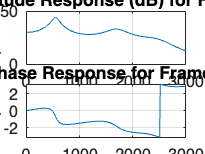

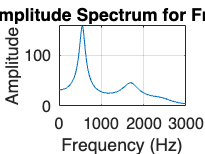

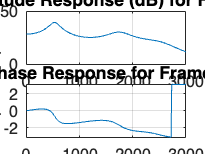

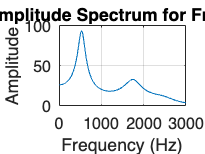

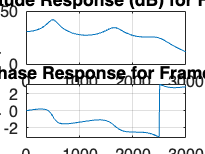

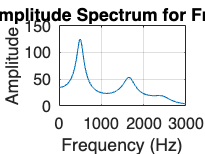

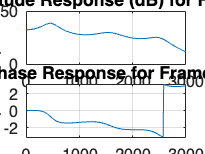

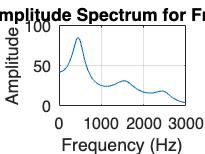

    %lpc filter
    base_number_point = 2048;
    [frequency_response, frequency_vector] = LPC_Filter(lpc_cofficient, fs,base_number_point);

    disp('LPC Coefficients for Frame 1:');

LPC Coefficients for Frame 1:


    disp(lpc_cofficient(1, :));

    1.0000   -1.4894    0.1859    0.1540    0.1167    0.0782    0.0427    0.0134   -0.0080   -0.0209   -0.0263   -0.0256   -0.0208   -0.0137   -0.0059    0.0015    0.0075    0.0116    0.0133    0.0129    0.0105    0.0066    0.0016   -0.0041   -0.0105   -0.0172   -0.0239   -0.0298    0.0715



    
    plot_frequency_limit = 3000;
    Formant_Frequency_Estimation(frequency_response, frequency_vector, plot_frequency_limit);

Frame 1 - Min Magnitude: -8.553, Max Magnitude: 44.0141
Detected Formant Frequencies for Frame 1:
   1.0e+03 *

    0.5491
    1.6904

Frame 2 - Min Magnitude: -8.145, Max Magnitude: 39.4329
Detected Formant Frequencies for Frame 2:
   1.0e+03 *

    0.5276
    1.7442

Frame 3 - Min Magnitude: -8.5797, Max Magnitude: 41.9319
Detected Formant Frequencies for Frame 3:
   1.0e+03 *

    0.4953
    1.6473
    2.3579

Frame 4 - Min Magnitude: -8.4569, Max Magnitude: 38.6045
Detected Formant Frequencies for Frame 4:
   1.0e+03 *

    0.4522
    1.5396
    2.4333



  153.6585  165.1685  167.0455  165.1685



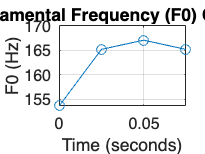

    % Mean_F0 = CalculateMeanF0(high_energy_frames, fs, frame_size, frame_overlap);


% Step 1: Calculate F0 values and smooth them
f0_values = CalculateMeanF0(high_energy_frames, fs, frame_size, frame_overlap);

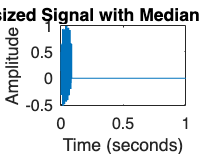

f0_values = min(f0_values, 255); % Upper limit of 255 Hz for realistic pitch
f0_values = max(f0_values, 85);  % Lower limit of 85 Hz
f0_values_smooth = movmean(f0_values, 5); % Smooth F0 values

% Set a median F0 to ensure consistent impulse train spacing
median_F0 = median(f0_values_smooth(~isnan(f0_values_smooth)));
T0_median = round(fs / median_F0);

% Step 2: Calculate a consistent scaling factor based on average frame energy
avg_frame_energy = mean(mean(abs(high_energy_frames), 2)); % Average energy across all frames

% Initialize synthesized signal
synthesized_signal = zeros(length(filter_signal), 1);
frame_step = round(frame_size * 0.25); 

% Step 3: Loop through each frame and apply LPC filtering with overlap-add synthesis
for i = 1:size(high_energy_frames, 1)
    T0 = T0_median;
    % Calculate frame indices for overlap-add synthesis
    start_index = (i - 1) * frame_step + 1;
    end_index = min(start_index + frame_size - 1, length(synthesized_signal));
    if start_index > length(synthesized_signal)
        break;
    end

    % Generate impulse segment with median period and apply consistent energy scaling
    impulse_segment = zeros(frame_size, 1);
    impulse_segment(1:T0:end) = 1;
    impulse_segment = impulse_segment * avg_frame_energy * 3; % Consistent amplitude scaling

    % Apply LPC filtering for the current frame
    frame_synthesized = filter(1, lpc_cofficient(i, :), impulse_segment);

    % Normalize each synthesized frame to maintain energy level
    if max(abs(frame_synthesized)) ~= 0
        frame_synthesized = frame_synthesized / max(abs(frame_synthesized));
    end

    % Overlap-add the frame_synthesized into the synthesized signal
    synthesized_signal(start_index:end_index) = synthesized_signal(start_index:end_index) + frame_synthesized;
end

% Step 4: Apply low-pass filtering to smooth out high-frequency noise
cutoff_freq = 3000; % Adjust cutoff as needed
smoothed_signal = lowpass(synthesized_signal, cutoff_freq, fs);

% Step 5: Apply a fixed gain factor for consistent loudness
gain_factor = 3.5;
smoothed_signal = smoothed_signal * gain_factor;

% Final normalization to avoid clipping
if max(abs(smoothed_signal)) > 1
    smoothed_signal = smoothed_signal / max(abs(smoothed_signal));
end

% Play the enhanced synthesized signal
sound(smoothed_signal, fs);

% Plot the final, enhanced signal
time_vector = (0:length(smoothed_signal) - 1) / fs;
figure;
plot(time_vector, smoothed_signal);
title('Enhanced Synthesized Signal with Median F0 and Uniform Scaling');
xlabel('Time (seconds)');
ylabel('Amplitude');
xlim([0, 1]); 


%Save Audio
audiowrite('synthesis.wav',smoothed_signal,fs)
